HOG = 16;
numBins = 16; % Deprecated No ens ha donat temps a fer els colors
strongestBRISK=100;
strongestFAST=100;
baseFolder = "./Train/";

% Fem servir uns models de noms de carpeta
folderPattern = fullfile(baseFolder, '*', 'TM');
folders = dir(folderPattern);

% Inisialitzem on les guardarem
modelFeatures = struct();

% Ara per a cada carpeta de serie
for i = 1:length(folders)
    % Agafem la carpeta TM (Train Model) on tenim els submodels
    currentFolder = fullfile(folders(i).folder, folders(i).name);
    
    % Agafem el nom de la carpeta on está aquest TM per saber la serie
    [parentPath, ~, ~] = fileparts(currentFolder);
    [modelName, ~, ~] = fileparts(parentPath);    
    [~, modelName, ~] = fileparts(modelName);     
    modelName = strrep(modelName, " ", "_");      % Eliminem espais que no l'hi agraden al Matlab
    
    % Busquem totes les carpetes que serán els submodels
    submodels = dir(currentFolder);
    submodels = submodels([submodels.isdir]);    % Filtrem les que no siguin directories y pares(. , ..)
    submodels = submodels(~ismember({submodels.name}, {'.', '..'})); 
    
    % Per a cada carpeta del submodel
    for sub = 1:length(submodels)
        submodel = submodels(sub).name; % Agafem el nom de la carpeta com a nom de submodel
        submodelPath = fullfile(currentFolder, submodel); 
               
        % Mirem que la carpeta tingui imatges
        if ~isempty(dir(fullfile(submodelPath, '*.jpg')))     
            % Inisialitzem l'struct amb els valors que agafarem de cada
            % submodel
            modelFeatures.(modelName).(submodel).keypoints = {};
            modelFeatures.(modelName).(submodel).HOGs = {};
            modelFeatures.(modelName).(submodel).corners = {};
            modelFeatures.(modelName).(submodel).im = {};

            % Carraguem la llista de les imatges del submodel en JPG
            imageFiles = dir(fullfile(submodelPath, '*.jpg'));
            
            % I processem per cada imatge
            for j = 1:length(imageFiles)
                % La carreguem amb fullfile per evitar errors amb
                % linux/windows/mac/etc...
                imagePath = fullfile(imageFiles(j).folder, imageFiles(j).name);
                img = imread(imagePath);

                % Guardem l'Imatge original
                modelFeatures.(modelName).(submodel).im{end+1} = img;
                
                % Per als keypoints la passem a blanc i negre
                grayImg = rgb2gray(img);
                
                % Fem servir els keypoints BRISK
                keypointsBRISK = detectBRISKFeatures(grayImg);
                modelFeatures.(modelName).(submodel).keypoints{end+1} = selectStrongest(keypointsBRISK,strongestBRISK);
                
                % FAST per als corners
                corners = detectFASTFeatures(grayImg);
                modelFeatures.(modelName).(submodel).corners{end+1} = selectStrongest(corners,strongestFAST);

                % I les Features de HOG
                hogFeatures = extractHOGFeatures(grayImg, 'CellSize', [HOG, HOG]);
                modelFeatures.(modelName).(submodel).HOGs{end+1} = hogFeatures;


            end
            

        end
    end
end

%clearvars -except modelFeatures;


## Tests

Imatge de Prova: 02499.jpg -> Model Detectat: Oliver_y_Benji (Submodel: Cara)


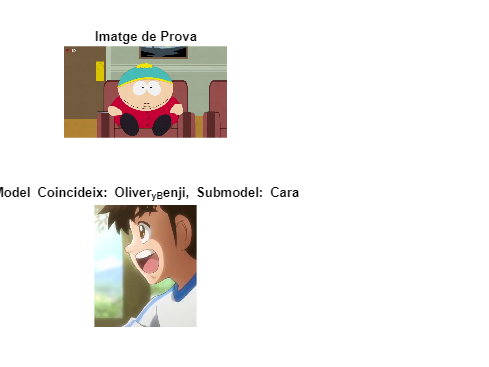

Imatge de Prova: Pokemon14177.jpg -> Model Detectat: Oliver_y_Benji (Submodel: Cara)


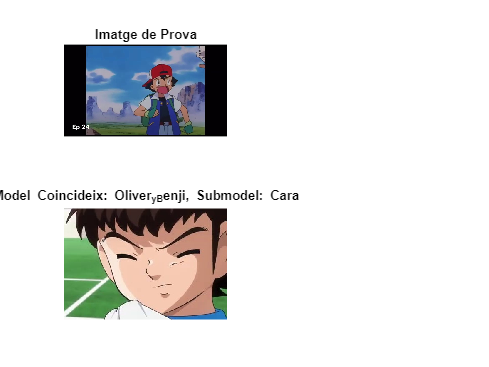

Imatge de Prova: Pokemon2370.jpg -> Model Detectat: Oliver_y_Benji (Submodel: Cara)


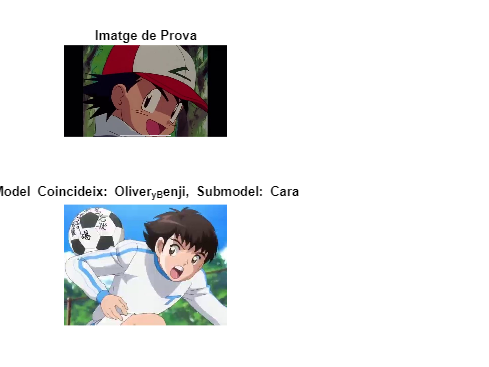

Imatge de Prova: SPONGE_BOB16349.jpg -> Model Detectat: Bob_esponja (Submodel: Espalda)


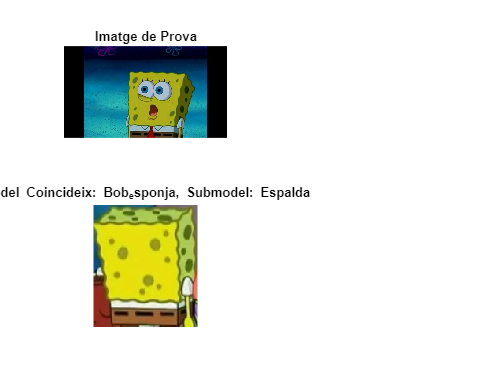

Imatge de Prova: Smurfs7824.jpg -> Model Detectat: pokemon (Submodel: Cara)


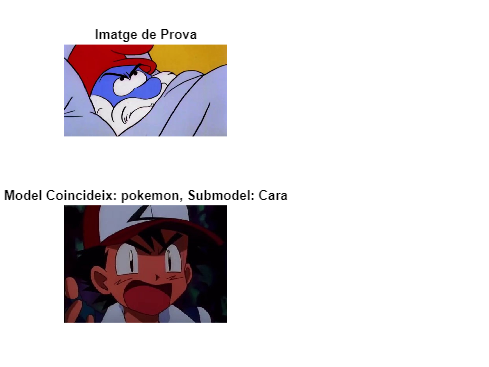

Imatge de Prova: TOM_AND_JERRY8774.jpg -> Model Detectat: Oliver_y_Benji (Submodel: Frontal)


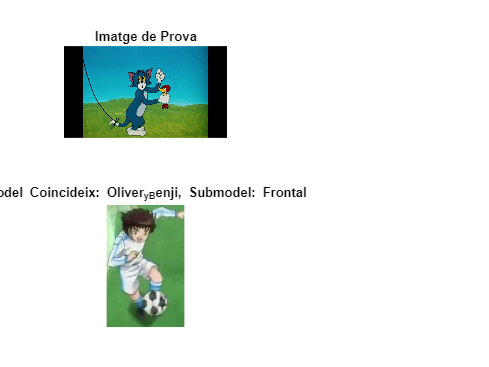

Imatge de Prova: TSUBASA10295.jpg -> Model Detectat: Oliver_y_Benji (Submodel: Cara)


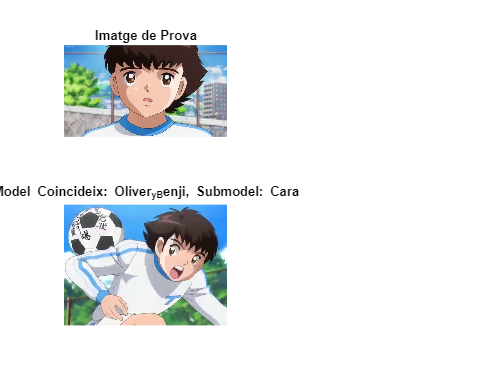

Imatge de Prova: TSUBASA119.jpg -> Model Detectat: Oliver_y_Benji (Submodel: Bebe)


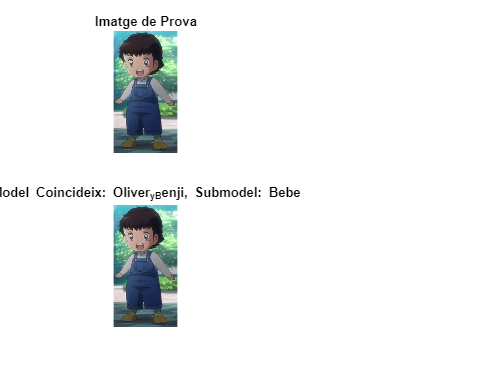

Imatge de Prova: TSUBASA409.jpg -> Model Detectat: Oliver_y_Benji (Submodel: Bebe)


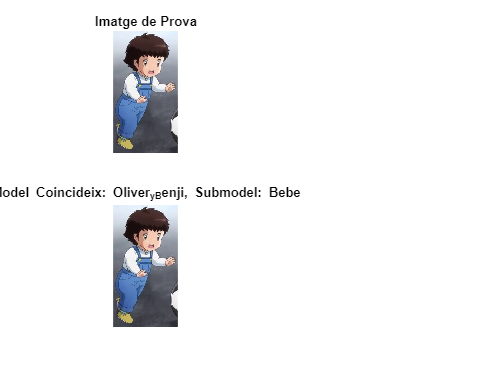

Imatge de Prova: adventure_time_0.jpg -> Model Detectat: Oliver_y_Benji (Submodel: Cara)


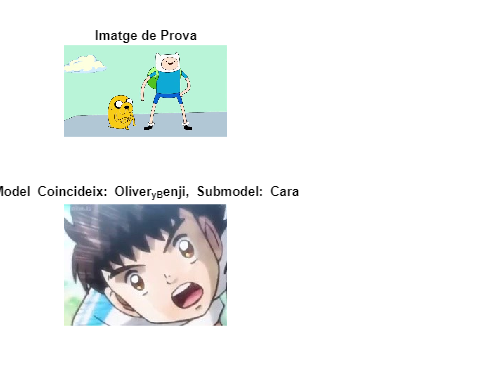

Imatge de Prova: adventure_time_230.jpg -> Model Detectat: Oliver_y_Benji (Submodel: Cara)


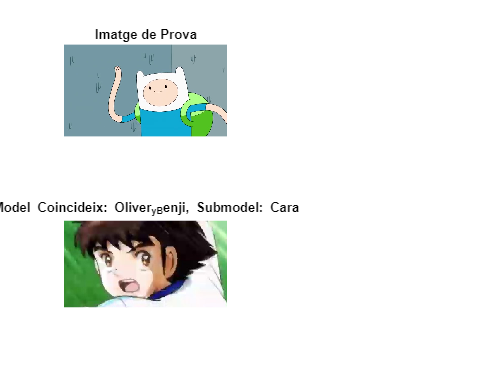

Imatge de Prova: family_guy12801.jpg -> Model Detectat: Gumball (Submodel: Muecas)


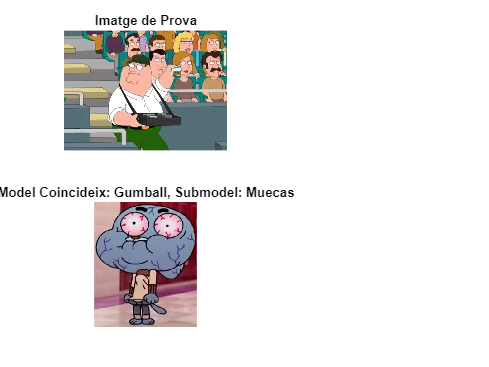

Imatge de Prova: family_guy1692.jpg -> Model Detectat: padre_de_familia (Submodel: Cara)


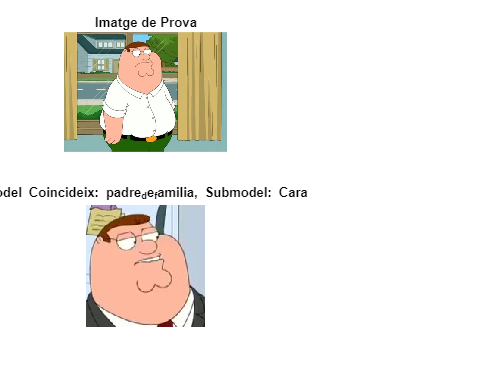

Imatge de Prova: family_guy7585.jpg -> Model Detectat: padre_de_familia (Submodel: Frontal)


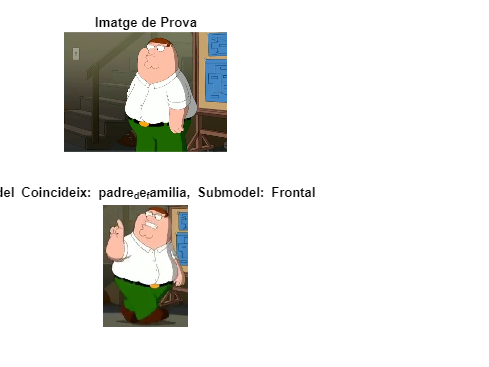

% Fase De Prova
% Definir la carpeta base per a les proves
baseTestFolder = './Test/'; % Ajusta aquest camí segons sigui necessari

% Inicialitzar resultats
results = struct();
threshold = 1.8; % Puntuació mínima per a una coincidència vàlida. Màxim = 3
BRISKweight=1;
FASTweight=1;
HOGweight=1;

% Definir la mida fixa de la imatge per redimensionar totes les imatges per a l'extracció de característiques HOG
fixedSize = [128, 64];  % Redimensionar imatges a 128x64 pixels

imageFiles = dir(fullfile(baseTestFolder, '*.jpg'));
% Bucle a través de cada imatge de prova per el test
for j = 1:length(imageFiles)
    testImagePath = fullfile(imageFiles(j).folder, imageFiles(j).name);
    testImg = imread(testImagePath);

    % Convertir la imatge de prova a gray scale
    grayTestImg = rgb2gray(testImg);

    % Calcular les característiques BRISK i FAST per a la imatge de prova
    testBRISK = detectBRISKFeatures(grayTestImg);
    testFAST = detectFASTFeatures(grayTestImg);
    
    % Seleccionar els punts més forts (per coincidir amb la fase d'entrenament)
    testBRISK = selectStrongest(testBRISK, strongestBRISK);
    testFAST = selectStrongest(testFAST, strongestFAST);
    
    % Redimensionar la imatge de prova a la mida fixa
    resizedTestImg = imresize(testImg, fixedSize);
    
    % Extreure característiques HOG de la imatge de prova redimensionada
    testHOG = extractHOGFeatures(resizedTestImg, 'CellSize', [HOG, HOG]);

    % Inicialitzar puntuacions de similitud
    bestScore = -Inf;
    bestModel = '';
    bestSubmodel = '';
    bestMatchedImg = [];

    % Comparar amb cada imatge d'entrenament de tots els models i submodels
    modelNames = fieldnames(modelFeatures);
    for k = 1:length(modelNames)
        %fprintf('Avaluant Model: %s\n', modelNames{k});
        submodelNames = fieldnames(modelFeatures.(modelNames{k}));
        for m = 1:length(submodelNames)
            %fprintf('Avaluant Submodel: %s\n', submodelNames{m});
            trainingImages = modelFeatures.(modelNames{k}).(submodelNames{m}).im;
            trainingBRISK = modelFeatures.(modelNames{k}).(submodelNames{m}).keypoints;
            trainingFAST = modelFeatures.(modelNames{k}).(submodelNames{m}).corners;
            trainingHOG = modelFeatures.(modelNames{k}).(submodelNames{m}).HOGs;

            % Comparar amb cada imatge d'entrenament per a aquest submodel
            for n = 1:length(trainingImages)
                % Redimensionar la imatge d'entrenament a la mida fixa
                resizedBestMatchedImg = imresize(trainingImages{n}, fixedSize);
                
                % Extreure característiques HOG de la imatge d'entrenament redimensionada
                trainingHOGFeatures = extractHOGFeatures(resizedBestMatchedImg, 'CellSize', [HOG, HOG]);

                % Comparar característiques BRISK (distància Hamming)
                briskMatches = matchFeatures(testBRISK.Location, trainingBRISK{n}.Location);

                % Comparar característiques FAST (utilitzant el detector de cantonades FAST)
                fastMatches = matchFeatures(testFAST.Location, trainingFAST{n}.Location);

                % Comparar característiques HOG (similitud cosinus)
                hogSimilarity = 1 - pdist2(testHOG, trainingHOGFeatures, 'cosine');
                % Combinar mètriques de similitud
                totalScore = HOGweight*hogSimilarity + BRISKweight*(length(briskMatches)/strongestBRISK) + FASTweight*(length(fastMatches)/strongestFAST);

                % Guardar el millor matching 
                if totalScore > bestScore
                    bestScore = totalScore;
                    bestModel = modelNames{k};
                    bestSubmodel = submodelNames{m};
                    bestMatchedImg = trainingImages{n};
                end

                %fprintf('Submodel: %s, Imatge d'Entrenament %d\n', submodelNames{m}, n);
                %fprintf('  Total: %.4f, BRISK: %d, FAST: %d, HOG: %.4f\n', totalScore, length(briskMatches), length(fastMatches), hogSimilarity);
            end
        end
    end

    % Mostrar i guardar el resultat
    if bestScore > threshold
        
        fprintf('Imatge de Prova: %s -> Model Detectat: %s (Submodel: %s)\n', imageFiles(j).name, bestModel, bestSubmodel);
    else
        fprintf("Imatge de Prova: %s -> No s'ha trobat cap coincidència\n", testImagePath);
    end

    % Visualització del millor matching
    figure;
    subplot(2, 2, 1); imshow(testImg); title('Imatge de Prova');
    if bestScore > threshold
        subplot(2, 2, 3); imshow(bestMatchedImg); title(['Model Coincideix: ' bestModel ', Submodel: ' bestSubmodel]);

        % Mostrar característiques coincidents (BRISK i FAST)
        matchedBRISKPointsTest = testBRISK.Location(briskMatches(:, 1), :);
        matchedBRISKPointsTrain = trainingBRISK{n}.Location(briskMatches(:, 2), :);
        matchedFASTPointsTest = testFAST.Location(fastMatches(:, 1), :);
        matchedFASTPointsTrain = trainingFAST{n}.Location(fastMatches(:, 2), :);

        % Mostrar coincidències BRISK
        % figure;
        % showMatchedFeatures(testImg, bestMatchedImg, matchedBRISKPointsTest, matchedBRISKPointsTrain, 'montage');
        % title('Característiques BRISK Coincidents');

        % Mostrar coincidències FAST
        % figure;
        % showMatchedFeatures(testImg, bestMatchedImg, matchedFASTPointsTest, matchedFASTPointsTrain, 'montage');
        % title('Característiques FAST Coincidents');
    else
        subplot(2, 2, 3); title("No s'ha trobat cap coincidència");
    end
    %subplot(2, 2, 4); plot(testHOG); title('Característiques HOG de Prova');
end